# feature extraction file for EEG

% this file pulls data from .data file and extracts features based on 
% annotations 

% this analysis assumes that data has already been filtered (functions may
% be needed to be added to filter data if it is flagged as discussed with
% kavya)



## visualizing pre-analysis

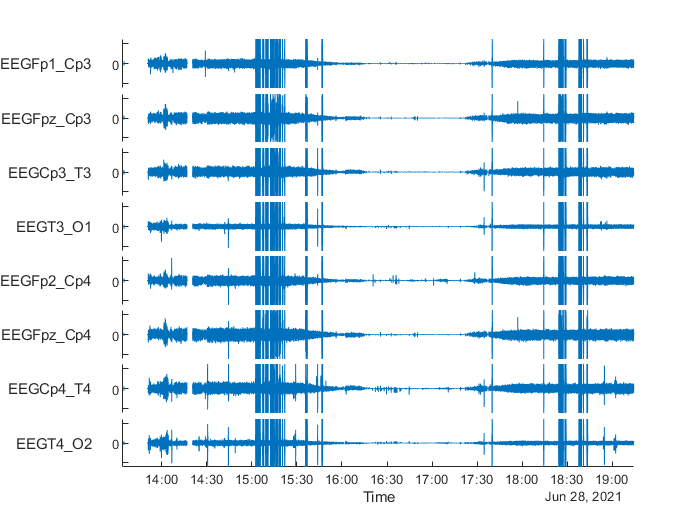

% visualizing entire dataset
h = stackedplot(allEDFs.data{'EEG'});
ax = findobj(h.NodeChildren, 'Type','Axes');
arrayfun(@(h)xline(h,allEDFs.annotations{'EEG'}.Onset(1,1),'LineWidth',1.5),ax)

% visualizing a portion of the dataset that was annotated as an event for a
% particular case
% stackedplot(allEDFs.data{'EEG'}(237100:249372,:)) 

## filtering out signal saturation periods

% signals that are above a certain threshold (abs(100)) will be changed to NaN.

allEDFs_filtered = allEDFs; % save allEDFs to another cell table
% determine size of table for for loop
table_size = size(allEDFs_filtered.data{'EEG'});
stackedplot(allEDFs_filtered.data{'EEG'}) % visualizing pre-filtering


saturation_indx1 = find(abs(allEDFs_filtered.data{'EEG'}{:, 1}) > 100); % find saturation indices
saturation_indx2 = find(abs(allEDFs_filtered.data{'EEG'}{:, 4}) > 100); % find saturation indices

% known datapoints outside of saturation threshold
allEDFs_filtered.data{'EEG'}{saturation_indx1(1,1), 1} 

ans = -108.3952

allEDFs_filtered.data{'EEG'}{saturation_indx1(2,1), 1}

ans = 102.6795

allEDFs_filtered.data{'EEG'}{saturation_indx2(1,1), 4} 

ans = -122.7405


% replace saturated datapoints with NaN
for i = 1:table_size(1,2)
    allEDFs_filtered.data{'EEG'}{(abs(allEDFs_filtered.data{'EEG'}{:,i}) > 50),i} = NaN;
end

% check that known datapoints are now "NaN"
allEDFs_filtered.data{'EEG'}{saturation_indx1(1,1), 1} % check that known datapoint is now "NaN"

ans = NaN

allEDFs_filtered.data{'EEG'}{saturation_indx1(2,1), 1} 

ans = NaN

allEDFs_filtered.data{'EEG'}{saturation_indx2(1,1), 4}

ans = NaN


y = stackedplot(allEDFs_filtered.data{'EEG'}) % visualizing post-filtering

y =   StackedLineChart with properties:

         SourceTable: [2611200×8 timetable]
    DisplayVariables: {'EEGFp1_Cp3'  'EEGFpz_Cp3'  'EEGCp3_T3'  'EEGT3_O1'  'EEGFp2_Cp4'  'EEGFpz_Cp4'  'EEGCp4_T4'  'EEGT4_O2'}
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties


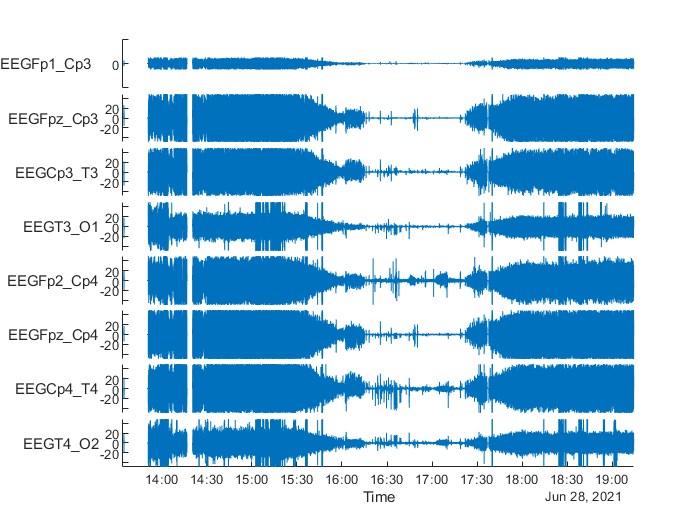

y =   StackedLineChart with properties:

         SourceTable: [2611200×8 timetable]
    DisplayVariables: {'EEGFp1_Cp3'  'EEGFpz_Cp3'  'EEGCp3_T3'  'EEGT3_O1'  'EEGFp2_Cp4'  'EEGFpz_Cp4'  'EEGCp4_T4'  'EEGT4_O2'}
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties


y.AxesProperties(1).YLimits = [-200 200]


% method that kavya came up with during out meeting 1/8/2022 to replace
% saturation indices with nan.
%saturation_indx = find(allEDFs_filtered.data{'EEG'}{:, 1} > 100);
%for i = 1:length(saturation_indx)
%    allEDFs_filtered.data{'EEG'}{saturation_indx(i), 1} = nan;
%end


## baseline mean determination

% find index of first instance of "intubat" (intubation)
index1 = find(contains(allEDFs_filtered.annotations{'EEG'}{:, 'Annotations'},'intubat', 'IgnoreCase',true));
onset1 = allEDFs_filtered.annotations{'EEG'}.Onset(index1(1,1));
[~, index] = ismember(allEDFs_filtered.data{'EEG'}.Time(:,1),onset1);
intubation_Index = find(index)

intubation_Index = 259585


% find index of first instance of "incis" (incision)
index2 = find(contains(allEDFs_filtered.annotations{'EEG'}{:, 'Annotations'},'incis', 'IgnoreCase',true));
onset2 = allEDFs_filtered.annotations{'EEG'}.Onset(index2(1,1));
[~, index] = ismember(allEDFs_filtered.data{'EEG'}.Time(:,1),onset2);
incision_Index = find(index)

incision_Index = 678529

% run function to determine start index for each EEG channel
channels = {'EEGFp1_Cp3','EEGFpz_Cp3', 'EEGCp3_T3', 'EEGT3_O1', 'EEGFp2_Cp4', 'EEGFpz_Cp4', 'EEGCp4_T4', 'EEGT4_O2'}

channels = 1×8 cell array
    {'EEGFp1_Cp3'}    {'EEGFpz_Cp3'}    {'EEGCp3_T3'}    {'EEGT3_O1'}    {'EEGFp2_Cp4'}    {'EEGFpz_Cp4'}    {'EEGCp4_T4'}    {'EEGT4_O2'}


start_index = nan(1,table_size(1,2));
for k = 1:length(channels)
    start_index(1,k) = baseline_mean(table_size, allEDFs_filtered, channels(1,k));
end
start_index % check for baseline start

start_index =         4737        4737        4737        4737        4738        4737        4737        4737



% check that there is not a lot of variance between start_index values. too
% large of a difference could indicate a problem with the baseline
% determination values and would need to be evaluated on a case-by-case
% basis
diffs = diff(start_index);
diffs = max(abs(diffs(diffs >= 0)));
if (diffs > 5)
    error("large variance among baseline start indices detected. largest difference was determined to be " + diffs)
end



% determining the baseline for all channels
baseline_preIntubation = nan(1,8);
baseline_postIntubation = nan(1,8);
baseline_Total = nan(1,8);
for i = 1:table_size(1,2)
    baseline_preIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):intubation_Index, channels(1,i)},'omitnan');  
    baseline_postIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index, channels(1,i)},'omitnan');  
    baseline_Total(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):incision_Index, channels(1,i)},'omitnan');
end
baseline_preIntubation

baseline_preIntubation =    -0.0386   -0.1125    0.0016    0.0806    0.0278   -0.0902   -0.1275    0.0876


baseline_postIntubation

baseline_postIntubation =    -0.0167    0.0423   -0.1430    0.0109   -0.0028    0.2266   -0.1783   -0.0128


baseline_Total

baseline_Total =    -0.0223    0.0025   -0.1055    0.0291    0.0051    0.1446   -0.1653    0.0130



% 15 second baseline windows
    % data from baseline regions is divided into 15 second windows and then
    % the mean is calculated to create one 15 second array per channel
rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;

% window_inds = start_index(1,1):window:intubation_Index
window_inds = max(start_index):window:intubation_Index

window_inds =         4738        6658        8578       10498       12418       14338       16258       18178       20098       22018       23938       25858       27778       29698       31618       33538       35458       37378       39298       41218       43138       45058       46978       48898       50818       52738       54658       56578       58498       60418       62338       64258       66178       68098       70018       71938       73858       75778       77698       79618       81538       83458       85378       87298       89218       91138       93058       94978       96898       98818


for i = 1:length(window_inds)
    baseline_windows(:,:,i) = allEDFs_filtered.data{'EEG'}{window_inds(i):window_inds(i)+window_size, :};
    % TODO = remove section where number is repeated excessively
end
mean_baseline = mean(baseline_windows, 3, 'omitnan')

mean_baseline =     2.0025    0.8938    0.6169    1.0188    1.3212    0.6308    1.2809    2.1885
    2.2184    1.2023   -0.2985    1.8714    1.5813    1.9568    1.3769    1.2703
    1.5159    1.4058   -0.7551    1.6265    1.1424    2.6570    0.5363    1.3918
    0.6566    0.5582   -0.5126    1.0780    0.3491    1.9377   -0.4869    1.0789
    0.2252    0.7232    0.5609    0.2349   -0.3897    1.0748   -0.0441    0.4017
    0.3941    1.3390   -0.8190   -0.2187    0.1406    0.8969   -0.9691   -0.4252
    0.5859    1.3993   -0.5088   -0.8300    0.9278    0.6333   -1.3154   -0.1238
    0.1483    1.3661   -0.3151   -0.7214    1.0116    0.8916   -1.2828    0.3847
    0.4425    1.4702    0.3418   -0.4742    0.6270    1.3004   -0.3945   -0.6003
    0.3532    1.3220    1.0344   -0.0987    0.2655    1.1245    0.1044    0.2106




z = baseline_windows(start_index, intubation_Index, allEDFs_filtered, window_size)

Unable to use a value of type table as an index.


% make this modular <-- define function to compute mean baseline for
% preintubation, post intubation, overall
% inputs: start index, end index, array, window size
% output: average across all windows

mean(allEDFs_filtered.data{'EEG'}{start_index(1,1):intubation_Index,1},'omitnan')
allEDFs_filtered.data{'EEG'}{intubation_Index + 1,2}

## analysis 

% from hospital team: abnormal events are annotated as alerts when duration
% of event exceeds 1 min

% from hospital team: abnormal events are observed when one or both
% hemishperes stray from baseline


% Note: for determining large amplitude changes between hemispheres,
% a table will be created containing the percentage change between the
% signal at a particular timepoint as compared to the baseline for each
% channel. if signals deviate for a minute or more, it will be marked as an
% event. 

% percent change
for i = 1:table_size(1,2)
    percent_change_table(:,i) = allEDFs_filtered.data{'EEG'}{incision_Index+1:end, channels(1,i)};
end
    % values will be saved to a new data table and analyzed from there
    percent_change_table = allEDFs_filtered.data{'EEG'}{stop_index+1:end,'EEGFp1_Cp3'};
    % change = 100*((signal-baseline)/baseline)
    percent_table_size = size(percent_change_table);
    percent_table_size = percent_table_size(1,1);
    for i = 1:percent_table_size
        percent_change_table(i) = 100 * abs((percent_change_table(i)-baseline)/baseline);
    end

% scan for features based on EEG alerts
    % plot percent change table with markers at 10 and 20 percent changes
    % from baseline 
    plot(percent_change_table(:,1))
    yline(10, '-','10 percent')
    yline(20,'-','20 percent')
    % text search for electrocautery and plot that over actual data
    
    

% isolation of features here

% Gaussian Mixture Model
[x,y,z] = baseline_mean(allEDFs)



## NOTES

% at some point I would like to create unit tests to verify that this code
% is able to handle a wide variety of datasets/data conditions and still
% perform well. I would like to generally how I would like the code to be
% written before doing this.

% baseline is supposed to be determined before CPB. I do not
% currently see in the annotations when that occurs, so I have
% selected a window based on what the OR team says that they
% currently do (see baseline.mlx for more details)

% not all of the annotations for all of the cases contain the word
% "incision", so it may be necessary to use a pre-incision baseline
% determination method, unfortunately. Since the OR team determines
% baselines both before and after incision, I would like to determine our
% baseline determination to emulate theirs, at least in the beginning
% stages of analysis

